# Testing Various Surface Mesh repair techniques and Vol Calculations

Volume calculations are dependent on the quality of the mesh

clearvars
clc
close all

### Add script specific paths

paths.objs = "/Users/ernesto/Documents/WORK/Research/Finger Lab/Dying Cell Project/Lysosome Analysis/cell OBJ reorientated";

file
paths.temp = "/Users/ernesto/Desktop/temp"; % writable location to stash obj files
if ~exist(paths.temp,"dir")
    mkdir(paths.temp)
end

### Load Data

[VL, cellT, idT] = load_lys_data(paths)

## Test Alpha Setting

The alpha input into **alphaShape** dramatically affects the volume calculated.

Not including an alpha input at all is likely the most accurate way to calculate volume

### Set Cells of Interest

coi = ["TB2_TCdying-01_cw" "TB2_TCdying-02_cw" "TB2_T2C-01_FR" "TB1_AP37_EM"];

- Three dying cells and one nice healthy looking cells (TB2_TC2-01_FR)

### Get Vertices

idx = 4

idx = 4

vCell = getVertsFromCellID(VL, coi(idx),1); % align point clouds to axes

### Align Vertices to axes

vCell = vCell - mean(vCell);
vCell = mmAlignSurface2Axes(vCell);
vCell = mmRotateSurfaceVertices(vCell,'y',90);

###  Create Alpha Shape

shp = alphaShape(vCell); % create alpha shape from vertices
shp.volume % calculate volume

ans = 191.8761

### AlphaShape to surfaceMesh

mesh = surfaceMesh(shp.Points,shp.boundaryFacets);

surfaceMeshShow(mesh)

'clean_mesh' in module 'pymeshfix_script' unrecognized.

% Ensure the Python environment with pymeshfix is active
if count(py.sys.path,'') == 0
    insert(py.sys.path,int32(0),'');
end

shp = alphaShape(vCell); % create alpha shape from vertices
shp.volume % calculate volume
clf
plot(shp)

ans = 191.8761

### Procrustes Method

vFaces = MyRobustCrust(vCell);

- results are terrible compared to alphaShape

## Use ManifoldPlus to create a watertight mesh surface

The following terminal command creates a watertight mesh

### Test One Cell

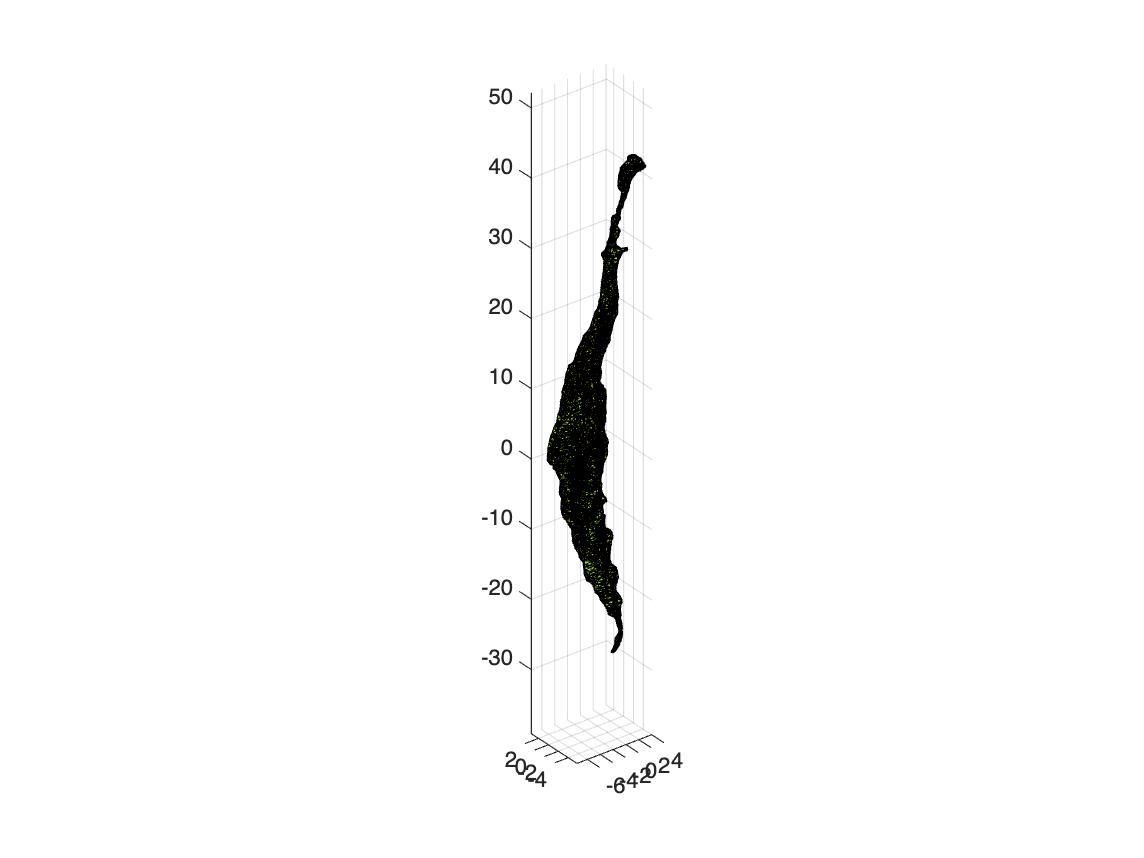

coi = ["TB2 Nucleus_26_cw_IV-ry"     "TB2 Nucleus_04_cw_cell-ry"];

idx = 1;
vCell = getVertsFromCellID(VL, coi(idx), 1);
shp = alphaShape(vCell);
mesh = surfaceMesh(shp.Points,shp.boundaryFacets);
mesh = cleanup_mesh(mesh);
surfaceMeshShow(mesh)

removeDefects(mesh,"nonmanifold-edges")
removeDefects(mesh,"degenerate-faces")
removeDefects(mesh,"unreferenced-vertices")
removeDefects(mesh,"duplicate-vertices")
removeDefects(mesh,"duplicate-faces")
surfaceMeshShow(mesh)

meshManifold = getWaterTightMesh(mesh, coi(idx),paths);


### Test Multiple cells

vols = zeros(numel(coi),2);
for n=1:numel(coi)
    vCell = getVertsFromCellID(VL, coi(n),1); % align point clouds to axes
    shp = alphaShape(vCell); % create alpha shape from vertices
    mesh = surfaceMesh(shp.Points,shp.boundaryFacets);
    mesh = cleanup_mesh(mesh);
    meshManifold = getWaterTightMesh(mesh, coi(n),paths);


##################### Arguments #####################
depth: 8.
input: /Users/ernesto/Desktop/temp/TB2 Nucleus_26_cw_IV-ry.obj.
output: /Users/ernesto/Desktop/temp/TB2 Nucleus_26_cw_IV-ry_manifold.obj.
#####################################################
vertex number: 6321    face number: 12854
Initialize AABB Tree...
Build Halfedges...
Split non-manifold vertices...
Rebuild Halfedges...
Gauss-seidel update...
Iter 0 with active vertex number 76784    
Iter 1 with active vertex number 76784    
Iter 2 with active vertex number 32441    
Iter 3 with active vertex number 5257    
Iter 4 with active vertex number 3589    
Iter 5 with active vertex number 3073    
Iter 6 with active vertex number 2670    
Iter 7 with active vertex number 2424    
Iter 8 with active vertex number 2280    
Iter 9 with active vertex number 2159    
Iter 10 with active vertex number 2013    
Iter 11 with active vertex number 1968    
Iter 12 with active vertex number 1862    
Iter 13 with active vertex numbe

    vols(n,1) = meshVolume(mesh.Vertices, mesh.Faces);
    vols(n,2) = meshVolume(meshManifold.Vertices, meshManifold.Faces);
end

vols

hvwr = viewer3d("BackgroundGradient","off","BackgroundColor",'k');
surfaceMeshShow(mesh,Parent=hvwr,Alpha=0.75,ColorMap="hot")
surfaceMeshShow(manifoldMesh,Parent=hvwr)

hvwr.Children(2).Alpha=0.75

mmPlotSurface

temp_folder = "/Users/ernesto/Desktop/temp";
ext = ".obj"
stl_in = fullfile(temp_folder, coi(idx)+ ext); % MATLAB surface mesh file
writeSurfaceMesh(mesh,stl_in) % write stl file
% stl_in = "/Users/ernesto/Desktop/TB1_AP37_EM.obj"

##################### Arguments #####################
depth: 8.
input: /Users/ernesto/Desktop/temp/TB2 Nucleus_26_cw_IV-ry.obj.
output: /Users/ernesto/Desktop/temp/TB2 Nucleus_26_cw_IV-ry_manifold.obj.
#####################################################
vertex number: 6321    face number: 12725
Initialize AABB Tree...
Build Halfedges...
Split non-manifold vertices...
Rebuild Halfedges...
Gauss-seidel update...
Iter 0 with active vertex number 76799    
Iter 1 with active vertex number 76799    
Iter 2 with active vertex number 32521    
Iter 3 with active vertex number 5348    
Iter 4 with active vertex number 3649    
Iter 5 with active vertex number 3124    
Iter 6 with active vertex number 2716    
Iter 7 with active vertex number 2471    
Iter 8 with active vertex number 2327    
Iter 9 with active vertex number 2197    
Iter 10 with active vertex number 2046    
Iter 11 with active vertex number 2001    
Iter 12 with active vertex number 1892    
Iter 13 with active vertex numbe

manifold_exe = "/Users/ernesto/github/ManifoldPlus/build/manifold" % the exe file
input_file = stl_in;
output_file = fullfile(temp_folder, coi(idx)+ "_manifold" + ext)
command = sprintf('%s --input %s --output %s --depth 8', manifold_exe, input_file, output_file)
[status,cmdout] = system(command);

if ~status
    disp("success!")
    disp cmdout
else
    disp('uh oh')
end

manifold_mesh = readSurfaceMesh(output_file);

v = meshVolume(manifold_mesh.Vertices, manifold_mesh.Faces)

meshVolume(vCell,vFaces)

### Plot alphaShape

clf
hp(1) = plot(shp,FaceColor='c',FaceAlpha=0.75,EdgeAlpha=0.25);

vCell = getVertsFromCellID(VL,coi(2),1); % align point clouds to axes

% vCell = vCell - mean(vCell);
% vCell = mmAlignSurface2Axes(vCell);

shp = alphaShape(vCell,1.5);
shp.volume
hold on
hp(2) = plot(shp,FaceColor='m',FaceAlpha=0.75,EdgeAlpha=0.25);

### Calculate volume

Part of MatGeom 

meshVolume(shp.Points,shp.boundaryFacets)

### Plot as Surface Mesh (part of Lidar Toolbox)

mesh = surfaceMesh(shp.Points,shp.boundaryFacets);
hvwr = viewer3d;
surfaceMeshShow(mesh,Parent=hvwr)

#### Add point cloud

PC = pointCloud(vCell);
mmfig
pcshow(PC)

## Calculate Volume by slice by slice

Here we plot each slice as stacked "ribbons", calculate the interior volume of each ribbon, and add them up

coi(2)
vl = VL(VL.Object == coi(4),:);

zs =  unique(vl.z);
volumes = zeros(numel(zs),1);

mmfig;
tiledlayout("flow","TileSpacing","none")
for n=1:numel(zs)
    la = vl.z == zs(n);
    x = [vl.x(la); vl.x(la)];
    y = [vl.y(la); vl.y(la)];
    z = [vl.z(la); vl.z(la)+0.08]; % double height of slice for volume measurement
    shp = alphaShape(x,y,z,2);
    % shp = alphaShape(x,y);

    % nexttile   

    plot(shp)
    axis off
    hold on
    
    % areas(n) = shp.area;
    volumes(n) = shp.volume;
end
sum(volumes)

### Use MATGeom to test volumes

meshVolume(hp(1).Vertices, hp(1).Faces)
meshVolume(hp(2).Vertices, hp(2).Faces)

- exact same result

mesh1 = surfaceMesh(hp(1).Vertices, hp(1).Faces);
mesh2 = surfaceMesh(hp(2).Vertices, hp(2).Faces);

writeSurfaceMesh(mesh1,coi(1)+'.obj')
writeSurfaceMesh(mesh2,coi(2)+'.obj')

### Plot Cells one row

coi = ["TB2_TCdying-01_cw" "TB2_TCdying-02_cw" "TB2_T2C-01_FR" "TB1_AP37_EM"];
la = ismember(cellT.Object,coi);
mmfig;
[hp, vol] = plot_same_ax(VL,cellT(la,:),[])

mesh = surfaceMesh(hp(2).Vertices, hp(2).Faces);
surfaceMeshShow(mesh)

meshVolume(hp(1).Vertices, hp(1).Faces)

meshVolume(mesh.Vertices,mesh.Faces)

surfaceMeshShow(mesh)

mesh2 = surfaceMesh(hp(2).Vertices, hp(2).Faces)
surfaceMeshShow(mesh2)

figure(Visible="on")

mmfig
tiledlayout("horizontal")


% fn = ["LysCount" "LysMeanVol" "LysMedianVol"];
% fx = ["meandiff","meandiff","mediandiff"];

fn = ["LysCount"  "LysMedianVol"];
fx = ["mediandiff","mediandiff"];
tl = ["Lysosome Count" "Lysosome Volume"];

hp ={};

for n=1:numel(fn)

la = cellT2.Health == "healthy"
x = cellT2.(fn(n))(la);
la = cellT2.Health == "dying"
y = cellT2.(fn(n))(la);

nexttile
hp{n} = gardnerAltmanPlot(gca,x,y,"Effect",fx(n));

ylabel(tl(n))
set(gca,xTickLabels = {'healthy' 'dying' 'diff'});
title('')
grid on

% sgtitle("Type II Healthy vs Dying")

end

#### Adjust plot settings

for n=1:2
set(hp{n}(1),...
 MarkerFaceColor='#b3e4fa',...
 MarkerFaceAlpha = 0.55,...
 MarkerEdgeColor='b',...
 SizeData=72);

set(hp{n}(2),...
 MarkerFaceColor='#e2d1ff',... purple
 MarkerEdgeColor = [0.25 0.25 0.25],...[0.7 0.6 0.8]
 MarkerFaceAlpha = 0.75,...
 SizeData=72);

set(hp{n}(3),...
    "LineWidth",.75)
% 
% set(hp{n}(4),...
%     "",1)
end


exportgraphics(gcf,fullfile(project_folder,"Figures","lys-Gardener-Altman.pdf"),Resolution=600)